# BMMO NXE Toolbox - Apply SBC

In this document, we discuss the different ways to apply a sbc correction to a dataset.

## Getting started

To accurately simulate the the TwinScan actuation using Matlab, in addition to the BMMO NXE Toolbox, we also need to load the CET model matlab module and the projection tooling matlab module.

module.include('\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\releases\BMMO-XY', ...
    '-sameNameControl', 'skip');

Dependent module: cet_model                                                                        R2021-07-21 (C:\Users\anair\AppData\Roaming\MathWorks\MATLAB\ModulesCache\7A3AEEA4CFEC13D9\R2021_07_21\CET_model)
Dependent module: DE_Overlay_Models:Patches                                                        R2021-08-31 (C:\Users\anair\AppData\Roaming\MathWorks\MATLAB\ModulesCache\B8A0A546C9BA8918\R2021_08_31\Patches)
Dependent module: DE_Overlay_Models                                                                R2021-08-31 (\\asml.com\eu\shared\nl011065\MO_tools\DE_Overlay_Models)
Including module: BMMO-XY                                                                          R2021-07-12 (C:\Users\anair\AppData\Roaming\MathWorks\MATLAB\ModulesCache\C5782B2E64FECDCC\R2021_07_12\BMMO-XY)



module.include('\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\releases\CET_model', ...
    '-sameNameControl', 'skip');
module.include('\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p', ...
    '-sameNameControl', 'skip');

Dependent module: YATA                                                                             R2017-10-28 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\YATA)
Dependent module: PICA_Tool                                                                        R2020-12-03 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\zeiss\PICA_Tool)
Dependent module: lens_heating                                                                     R2021-02-18 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\lens_heating)
Dependent module: ProjectionCommon                                                                 R2020-03-11 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\common)
Dependent module: pro_data                                                  

Dependent module: DE_Overlay_Models:Basics                                                         R2021-08-31 (C:\Users\anair\AppData\Roaming\MathWorks\MATLAB\ModulesCache\EB9C5BE20DD1A006\R2021_08_31\Basics)
Dependent module: DE_Overlay_Models:Sandbox                                                        R2021-08-31 (C:\Users\anair\AppData\Roaming\MathWorks\MATLAB\ModulesCache\A9A08C1DFE97B2C2\R2021_08_31\Sandbox)
Dependent module: CSR_calculator                                                                   R2020-01-08 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\CSR\CSR_calculator)
Dependent module: CSR                                                                              R2020-01-08 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\Projection_tools\CSR)
Dependent module: Administrative                                                                   R2021-0

Dependent module: DF_TWIN                                                                          R2021-02-17 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001\DF_TWIN)
Dependent module: 211001                                                                           R2021-07-05 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p\releases\REL_2127_211001)
Including module: Projection Toolbox                                                               R2021-07-12 (\\asml.com\eu\shared\nl011032\Projection_tooling\projection_toolbox_p)


## SBC structure

In the 'getting started' page we saw the two most common ways of getting an sbc structure in Matlab; loading it from a zip file from the output of the matlab model:

In addition we can also parse an available ADELsbcOverlayDriftControlNxe.xml or ADELsbcOverlayDriftControlNxerep.xml file directly into an sbc structure:

data_path        = '\\asml.com\eu\shared\nl011052\DE_Metro_tools\EUV\etc\BMMO-NXE\';
sbc_filename     = 'ADELsbcOverlayDriftControlNxe.xml';
sbc              = bmmo_kt_process_SBC2([data_path, sbc_filename]);
sbc_rep_filename = 'ADELsbcOverlayDriftControlNxerep.xml';
sbc_from_rep     = bmmo_kt_process_SBC2rep([data_path, sbc_rep_filename]);

Parsing ADELsbcOverlayDriftControlNxerep


The BMMO-NXE toolbox SBC structure `sbc` is a Matlab structure consisting of the following fields:

- `sbc.IR2EUV`: A 1x1 double with the value of the IR2EUV update.

- `sbc.SUSD`: A 1x4 structure containing the SUSD correction (6par intrafield per chuck and scan direction. Out of these, only Translation Y will be nonzero.)

- `sbc.MI`: A 1x1 structure containing the 1x2 structures `wse` and `wsm`, which contain, per chuck, the YTX and XTY mirror maps. The YTX mirror (also known as 'X-mirror') map gives the dx overlay values at 401 evenly-spaced y-coordinates between -0.2m and 0.2m. The XTY mirror (also known as 'Y-mirror') map gives the dy overlay values at 401 evenly-spaced x-coordinates between -0.2m and 0.2m.

- `sbc.BAO`: A 1x2 struct array containing the BAO correction parameters per chuck.

- `sbc.KA`: A 1x1 struct array containing the 1x2 structures grid_2de and grid_2dc containing the KA corrections.

- `sbc.ffp`: A 1x2 struct array containing the average 'field fingerprint' per chuck. When output by the model, this is the average of the dense fields in the BMMO-NXE layout after removing all the other corrections. When the SBC2 correction is actuated on scanner, the ffp is input to the inline SDM model, in which it is used to calculate the inline SDM correction.

## Apply SBC

The basic way to generate the fingerprints for each field of the `sbc` structure is by applying the `sbc` corrections on the bmmo input structure. In the example given below, the the fingerprints are generated by appling the `sbc` corrections on a default BL3 input structure.

input_struct = bmmo_input_to_bl3(bmmo_default_input);
input_struct.info.F.machine_type = 'NXE3600D';
input_struct.info.report_data.inline_sdm_model = 'BaseLiner 3';
sbc_fingerprint = bmmo_apply_SBC(input_struct, sbc);

The output `sbc_fingerprint` is a structure containing the fingerprints of the `sbc` correction on the layout of `input_struct`. Note that `input_struct` is used only to provide the single mark field layout; the overlay values in the structure will be ignored.

The fields of the `sbc_fingerprint` structure are as follows:

- `WH`: Overlay structure containing the wafer heating correction fingerprint. If `input_struct` is a valid input structure, the WH feed-forward correction from the exposure is used to generate this fingerprint. Otherwise, this fingerprint is zero.

- `MI`: Overlay structure containing the mirror correction fingerprint.

- `SUSD:` Overlay structure containing the SUSD correction fingerprint

- `BAO`: Overlay structure containing the BAO correction fingerprint.

- `KA`: Overlay structure containing the KA correction fingerprint. Since KA is disabled in the model, this is always zero.

- `INTRAF`: Overlay structure containing the intrafield correction fingerprint. This is an 18par/33par fit of the field fingerprint `sbc.ffp`.

- `TotalSBCcorrection`: Overlay structure containing the total SBC correction.

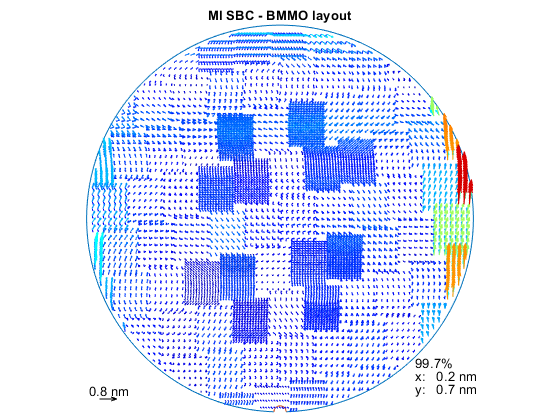

ovl_plot(sbc_fingerprint.MI, 'vcolor', 'scale', 0, 'title', ...
    'MI SBC - BMMO layout');

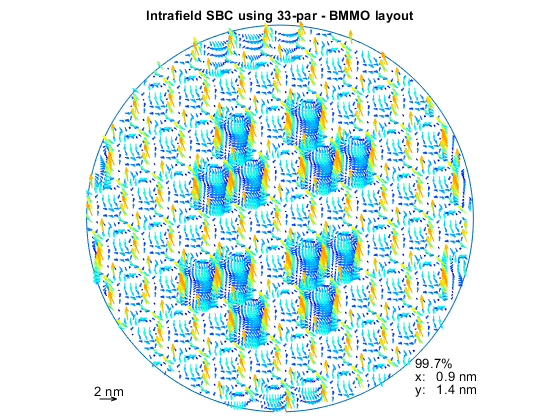

ovl_plot(sbc_fingerprint.INTRAF, 'vcolor', 'scale', 0, 'title', ...
    'Intrafield SBC using 33-par - BMMO layout');

bmmo_apply_sbc can be called with an optional constant` scaling_factor, `which specifies a scaling factor for the sbc corrections (default: 1) and additional outputs:

scaling_factor = 1;
[sbc_fingerprint, ff_6p, sbc_fingerprint_smf] = bmmo_apply_SBC(input_struct, sbc, scaling_factor);

the `ffp_6p `is the fingerprint of the feedforward BAO (obtained from MI and KA on measurer side) and `sbc_fingerprint_smf` similar to `sbc_fingerprint,` a structure containing the fingerprints of the `sbc` correction but on single mark field layout (input_struct).

Other functions to apply the `sbc` correction are available depending on the given input and/or expected output. 

For instance sbc corrections can be applied to any template `ml structure`:

ml = ovl_create_dummy('nlayer', 1);
ml.info.F.chuck_id = {'CHUCK_ID_1'};
sbc_fingerprint_ml = bmmo_apply_SBC_to_ml(ml, sbc, scaling_factor);

in which `scaling_factor` constant and the `options` structure are optional input arguments. The output structure is again similar as before, the sbc fingerprints on the template layout:

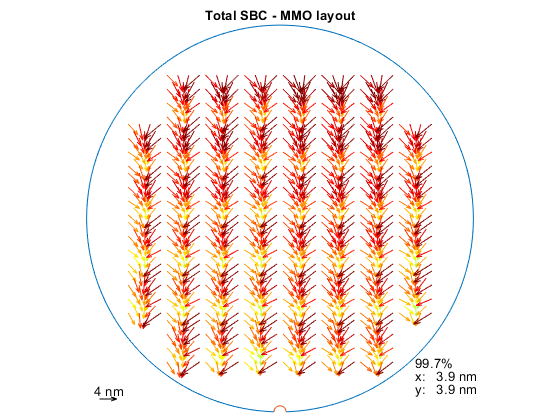

ovl_plot(sbc_fingerprint_ml.TotalSBCcorrection, 'vcolor', 'scale', 0, 'title', ...
    'Total SBC - MMO layout');

To simulate in the inline SDM model for intrafield, instead of an 18- or 33-par fit, bmmo_apply_sbc_(to_ml_)inilne_SDM can be used:

sbc_fingerprint_inlineSDM = bmmo_apply_SBC_inline_SDM(input_struct, sbc, scaling_factor);

Using Inline SDM configuration:bl3_3600D_model_configuration


The output structure is again the same as before, but now sbc_fingerprint_inlineSDM.INTRAF contains the inline SDM result:

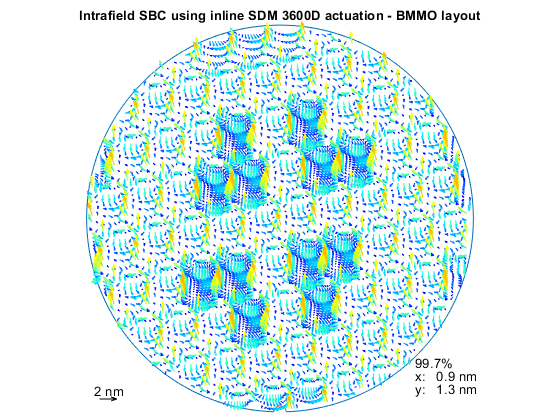

ovl_plot(sbc_fingerprint_inlineSDM.INTRAF, 'vcolor', 'scale', 0, 'title', ...
    'Intrafield SBC using inline SDM 3600D actuation - BMMO layout');

When comparing the 33-par fit and the inline SDM results, we can see that there is a small delta:

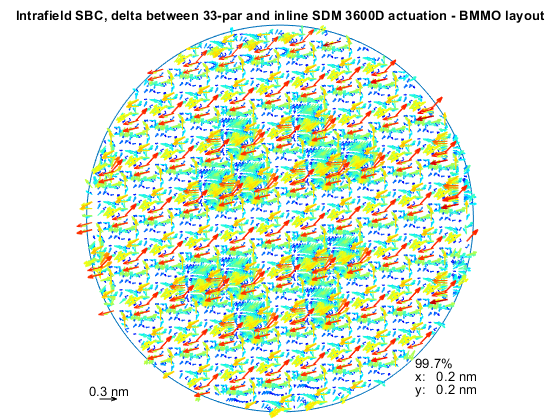

ml_intra_delta = ovl_sub(sbc_fingerprint.INTRAF, sbc_fingerprint_inlineSDM.INTRAF);
ovl_plot(ml_intra_delta, 'vcolor', 'scale', 0, 'title', ...
    'Intrafield SBC, delta between 33-par and inline SDM 3600D actuation - BMMO layout');